# Train a CNN classifier 

This example shows how to create and train a simple convolutional neural network (CNN) for deep learning classification. Convolutional neural networks are essential tools for deep learning, and are especially suited for image recognition.

The example demonstrates how to: 

- Load and explore image data.

- Define the network architecture.

- Specify training options.

- Train the network.

- Predict the labels of the validation sample data and calculate the classification accuracy.

- Save the network to evaluate it on new data (test set).

clear
close all

We load the train set (see the README file in ../DATASETS/IMAGES/Mammography_micro)

dataset_path='/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/'

dataset_path = '/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/'

imds_M = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

`ImageDatastore` is an object to manage a collection of image files, where each individual image fits in memory, but the entire collection of images does not necessarily fit. 

imds_M

imds_M =   ImageDatastore with properties:

                       Files: {
                              ' .../CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_2_0.pgm_1.pgm';
                              ' .../CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_2_0.pgm_2.pgm';
                              ' .../CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_2_0.pgm_3.pgm'
                               ... and 393 more
                              }
                     Folders: {
                              '/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train'
                              }
                      Labels: [0; 0; 0 ... and 393 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                

We can visualize the list of files contained in the datastore 

imds_M.Files

ans = 396×1 cell array
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_2_0.pgm_1.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_2_0.pgm_2.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_2_0.pgm_3.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_2_0.pgm_4.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_4_0.pgm_1.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_4_0.pgm_2.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_4_0.pgm_3.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0002s1_4_0.pgm_4.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/0003s1_2_0.pgm_1.pgm'}
    {'/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Train/0/

size(imds_M.Files)

ans =    396     1


We can visualize a single image

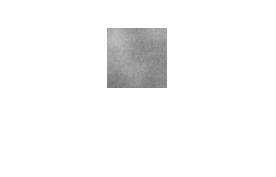

imshow(imds_M.Files{37})

We can visualize some sample images

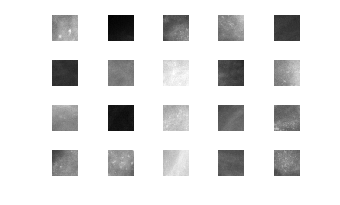

figure;
perm = randperm(size(imds_M.Files,1),20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds_M.Files{perm(i)});
end

We can count the amount of images containing microcalcifications (187), and those representing healthy tissue (209)

imds_M.Labels

ans = 396×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


sum(imds_M.Labels == '1') % images with microcalcifications

ans = 187

sum(imds_M.Labels == '0') % images of healthy tissue

ans = 209

We can read an image, check its size and display it 

img = readimage(imds_M,23);
size(img)

ans =     60    60


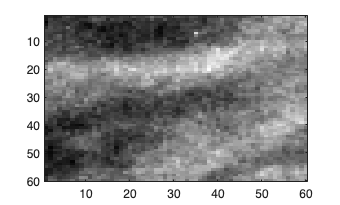

figure; imagesc(img); colormap gray

To define the train and validation set we can use the function `splitEachLabel, `which split ImageDatastore labels by proportions

numTrainFiles = 140;
[imdsTrain,imdsValidation] = splitEachLabel(imds_M,numTrainFiles,'randomize');

in this case, thi first datastore, imdsTrain, contains numTrainFiles, randomly selected within the sample (randomly assigns the specified proportion of files from each label to the new datastores).

## Define Network Architecture

Define the convolutional neural network architecture.

A batch normalization layer normalizes each input channel across a mini-batch.

A max pooling layer performs down-sampling by dividing the input into rectangular pooling regions, and computing the maximum of each region

layers = [
    imageInputLayer([60 60 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ];

This is a quite standard architecture, you can try your own network.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...  % 500
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'MiniBatchSize', 50);
% 'ValidationFrequency',20 means that validation is performed every 2 training iterations

Train the network

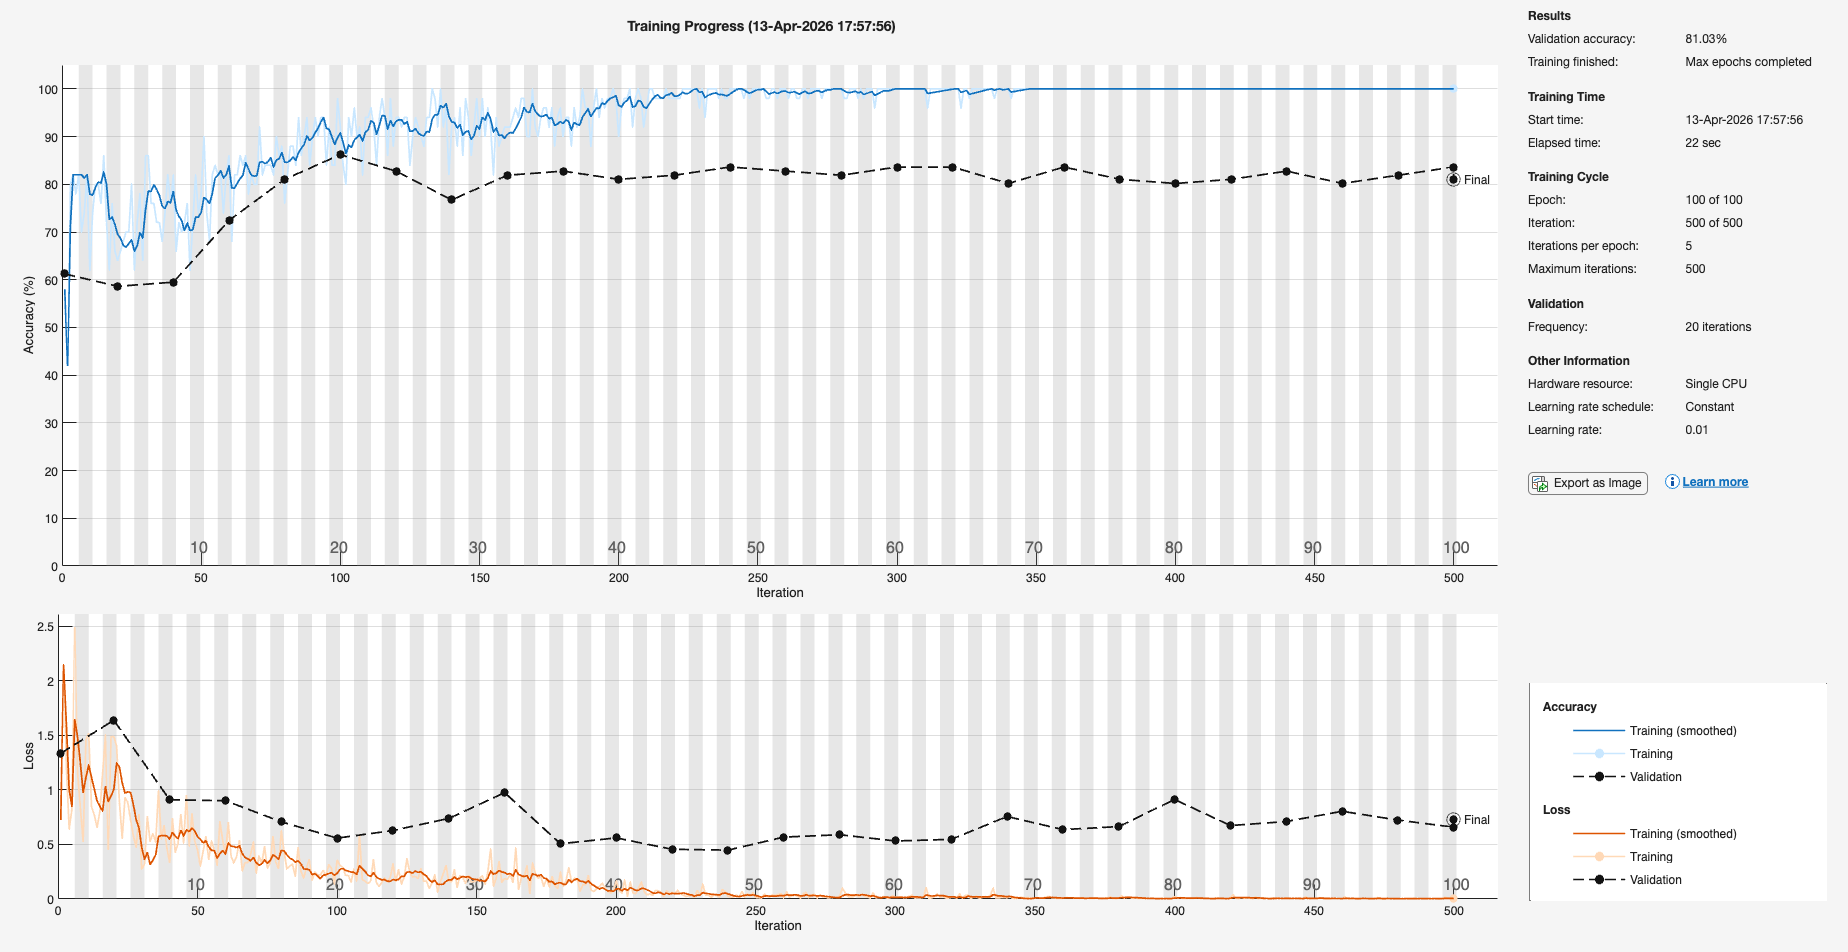

net = trainNetwork(imdsTrain,layers,options);

 `trainNetwork` uses a GPU if there is one available. If there is no available GPU, then it uses CPU.

The `analyzeNetwork``(net)` function analyzes the deep learning network architecture. It detects errors and issues in the network, and provides detailed information about the network layers.

analyzeNetwork(net)

Evaluate network performace on validation data

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.8103

We can visualize some correctly classified images:

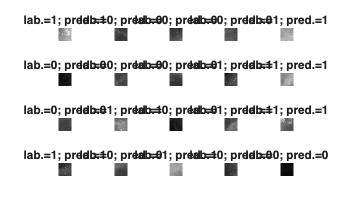

figure; title('Correctly classified ')
idx_outOK=find(YPred == YValidation);
perm = randperm(sum(YPred == YValidation),20);
for i = 1:20
    subplot(4,5,i);
    imshow(imdsValidation.Files{idx_outOK(perm(i))});
    title(strcat('lab.= ',char(YValidation(idx_outOK(perm(i)))), ...
        '; pred.= ',char(YPred(idx_outOK(perm(i))))))
    
end

... and some misclassified images

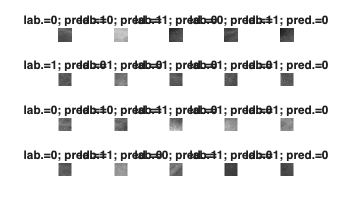

figure; title('Misclassified ')
idx_outOK=find(YPred ~= YValidation);
if(sum(YPred ~= YValidation)>20)
    perm = randperm(sum(YPred ~= YValidation),20);
    for i = 1:20
        subplot(4,5,i);
        imshow(imdsValidation.Files{idx_outOK(perm(i))});
        title(strcat('lab.= ',char(YValidation(idx_outOK(perm(i)))), ...
            '; pred.= ',char(YPred(idx_outOK(perm(i))))))
    end
else
    for i = 1:sum(YPred ~= YValidation)
        subplot(4,5,i);
        imshow(imdsValidation.Files{idx_outOK(i)});
        title(strcat('lab.= ',char(YValidation(idx_outOK(i))), ...
            '; pred.= ',char(YPred(idx_outOK(i)))))
    end
end

## Save the trained network

We can save the network to use it later on to classify new data

%save net_micro_train280_epochs500_acc88_500epochs net
save net_name net